# EE170A Project 1

Alexandre Leon 504941684 part 2 and 3

## Part 2: Sellmeier equation for refractive index

Sellmeier equation gives the refractive index for a certain material.

We will show the variation of refractive index based on wavelength for $\mathrm{Ge}O_2$


$$n^2(\lambda) = 1
+ \frac{A_1 \lambda^2 }{ \lambda^2 - \lambda_1^2}
+ \frac{A_2 \lambda^2 }{ \lambda^2 - \lambda_2^2}
+ \frac{A_3 \lambda^2 }{ \lambda^2 - \lambda_3^2}$$


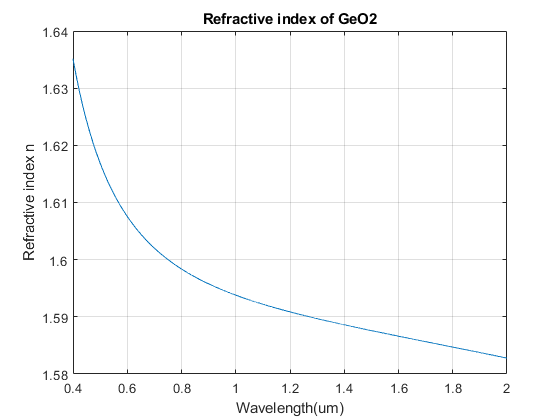

x = linspace(0.4,2,10000) .*1e-6; %wavelength
a1 = 0.80686642; a2 = 0.71815848; a3 = 0.85416831; %input constants
lam1 = 0.068972606e-6; lam2 = 0.15396605e-6; lam3 = 11.841931e-6;
n = computeSellmeier(a1,a2,a3,lam1,lam2,lam3, x);
plot(x .*1e6,n); xlabel("Wavelength(um)"); ylabel("Refractive index n"); title('Refractive index of GeO2');grid on;

## Part 3: Fabry-Perot cavity

We study a Favry-Perot cavity with following parameters

L = 250e-6; %Mirror separation 250 um
R = 0.9; % 90% Reflectivity
I0 = 1;


$$I_{cavity} = \frac{I_0}{(1-R)^2 + 4Rsin^2(kL)}$$


where $k = \frac{2\pi n }{\lambda}$ and $\upsilon = \frac{c}{\lambda}$

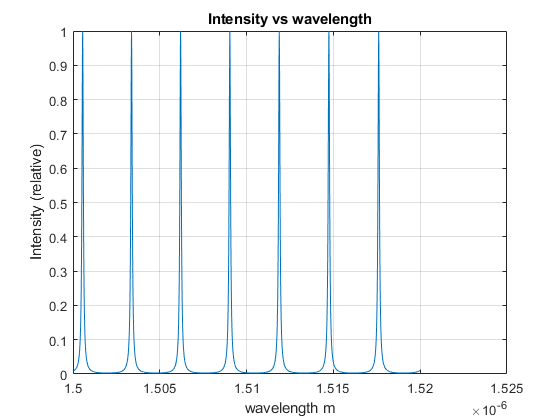

wavelength = linspace(1500,1520,100000) .*1e-9;
n_3 = computeSellmeier(a1,a2,a3,lam1,lam2,lam3,wavelength);
[I, mus,k] = computeImus(I0, R, wavelength, n_3, L);
plot(wavelength, I ./100); title('Intensity vs wavelength'); xlabel('wavelength m'); ylabel('Intensity (relative)'); grid on;

(b) To find the mode, we look use the following relationship


$$m = \frac{2L}{\lambda_m}$$


From the peak detection, we find the closest mode to 1500nm is

m = 2*L/(1500e-9)

m = 333.3333

This corresponds to mode m = 333 (integer)

(c) Finesse is given by the following relationship


$$F = \frac{\pi R^{1/2}}{1-R}$$


F = (pi*R^0.5)/(1-R)

F = 29.8038

(d) The Free Spectral Range (FSR) is found using the following relationship


$$\upsilon_f= \frac{c}{2L}$$


FSR = 3e8 /(2*L)

FSR = 6.0000e+11

(e) The spectral width is


$$\delta \upsilon_m = \frac{\upsilon_f}{F}$$


spectralWidth = FSR/F

spectralWidth = 2.0132e+10

## Part 2 functions

function n = computeSellmeier(a1,a2,a3,lam1,lam2,lam3, x)
    f1 = (a1.*(x.^2)) ./( (x.^2) - lam1^2);
    f2 = (a2.*(x.^2)) ./( (x.^2) - lam2^2);
    f3 = (a3.*(x.^2)) ./( (x.^2) - lam3^2);
    n2 = 1 + f1 + f2 + f3;
    n = sqrt(n2);
end

## Part 3 functions

function [I, mus,k] = computeImus(I0, R, wavelength, n, L)
    k = (2.*pi) .*n ./wavelength;
    I = I0 ./ ( (1 - R)^2 +4*R*sin(k.*L).^2);
    mus = (3e8) ./(wavelength);
end